% add path to functions/scripts
addpath C:\Users\nlab\Desktop\GitHub\ratrix\analysis\KC\KC_thresh_functions

% load individual vars into group cell arrays
%[nGroup, nthVarsFilePaths, groupStimDetails, groupSubjData, groupSubjName, groupDate, groupTrialCond, groupNumPreStimFrames, groupNumPostStimFrames, groupIdxOnsetsMeetsCriteria, groupOnsetDf, groupPeakFrameIdx, groupStimOnsetFrame, groupBaselineIdx, groupBaselinedActIm, groupRoundXpts, groupRoundYpts, groupPTSdfof, groupMeanSpeedAllTrials, groupIdxRunTrials, groupIdxStatTrials, groupIdxSmallPupilTrials, groupIdxLargePupilTrials, groupLongAxis, groupMeanPupilDiameterAllTrials, groupRunThresh, groupPupThresh] = makeGroupStruct();
% if no pup data:
[nGroup, nthVarsFilePaths, groupStimDetails, groupSubjData, groupSubjName, groupDate, groupTrialCond, groupNumPreStimFrames, groupNumPostStimFrames, groupIdxOnsetsMeetsCriteria, groupOnsetDf, groupPeakFrameIdx, groupStimOnsetFrame, groupBaselineIdx, groupBaselinedActIm, groupRoundXpts, groupRoundYpts, groupPTSdfof, groupMeanSpeedAllTrials, groupIdxRunTrials, groupIdxStatTrials, groupRunThresh] = makeGroupStruct_noPup();

% get stim conditions in order of trial & list of stim params to loop thru
% (This needs to be done new w/in the loop too each sess since the order of trialCond matters.. right now it's jsut to define cont & durat etc)
n = 1;
[durOrderedByTrialMeetCriteria,uniqueDurations,conOrderedByTrialMeetCriteria,uniqueContrasts,conAndDurOrderedByTrialMeetCriteria] = getStimParams4loops(n,groupStimDetails,groupTrialCond,groupIdxOnsetsMeetsCriteria);

% in preparation for making pixel wise figures of flurescene at different stim conditions,
% make figure legends
[reigons,cons4Legend,cons4axes,durs4Legend,durs4Axes] = getSubtitleLegendNaxesInfo(uniqueContrasts,uniqueDurations);
reigons
cons4Legend
durs4Legend 

% STAT & RUN SAME HISTO

%durat = 1:length(uniqueDurations);
durat = 1

cont = 1:length(uniqueContrasts)
%cont = 7

visArea = 1 % V1
%visArea = 2; % RL
%visArea = 3; % AL
%visArea = 4; % AM 
%visArea = 5; % control

%state = 'loRun'
state = 'loRun'

[allSess_allConsAllPtsAllDurs_pkDfEachTrial] = Histo_byBehState_noPup(nGroup,state,groupStimDetails,groupTrialCond,groupIdxOnsetsMeetsCriteria,groupPTSdfof,groupPeakFrameIdx,groupBaselineIdx,groupIdxStatTrials,groupIdxRunTrials,visArea,durat,cont,conAndDurOrderedByTrialMeetCriteria,uniqueContrasts,uniqueDurations);

size(allSess_allConsAllPtsAllDurs_pkDfEachTrial)
% tip - index like this -
% allSess_allConsAllPtsAllDurs_pkDfEachTrial{1,n}{1,d}{1,i}{1,c}

% STAT & RUN SAME HISTO

%durat = 1:length(uniqueDurations);
durat = 1

cont = 1:length(uniqueContrasts)
%cont = 7

visArea = 1 % V1
%visArea = 2; % RL
%visArea = 3; % AL
%visArea = 4; % AM 
%visArea = 5; % control

sess = 1:nGroup
%sess = 1

numBins = 25;

yMax = 0.2;
yLimit = [0 yMax];

xMax = 0.25;
xMin = -0.2;
xLimit = [xMin xMax];
xTickRange = [-0.1:0.05:xMax];
xTickLabelRange = [-0.1:0.1:xMax];

% GROUP EACH SESS OVERLAYED DIFF COLOR

figure

formatSpec = 'v.a.: %1.f, d: %1.f, state: %s';
titleText = sprintf(formatSpec,visArea,durat,state);
suptitle(titleText)

clear n
for n = sess
    
    clear numTrialsEachCon_allSess
    
    clear d
    for d = durat
        
        clear i
        for i = visArea
            
            clear numTrialsEachCon_eachSess
            clear numTrialsEachCon_sumAllSess
            
            clear c
            for c = cont
                
                clear nthDthCth_pkDfEachTrial
                nthDthCth_pkDfEachTrial = allSess_allConsAllPtsAllDurs_pkDfEachTrial{1,n}{1,d}{1,i}{1,c};
            
                % for nth trial, cth contrast, save num of trials at this contrast
                numTrialsEachCon_eachSess(n) = length(nthDthCth_pkDfEachTrial);
                % rolling sum 
                numTrialsEachCon_sumAllSess = sum(numTrialsEachCon_eachSess);
                
                subplot(ceil(sqrt(length(uniqueContrasts))),ceil(sqrt(length(uniqueContrasts))),c) % make a subplot for each contrast
                %title(sprintf('c = %0.3d',uniqueContrasts(c)))
                
                h1 = histogram(nthDthCth_pkDfEachTrial,numBins,'Normalization','probability');
                
                clear mnDf
                mnDf = mean(nthDthCth_pkDfEachTrial);
                clear y
                y = 0;
            
                hold on
                    
                stdev = (std(nthDthCth_pkDfEachTrial))/(sqrt(length(nthDthCth_pkDfEachTrial)));
                
                h2 = scatter(mnDf,y,'*','r');
                
                formatSpec = 'c=%s, mn=%0.3f, st=%0.3f, n=%1.0f';
                title(sprintf(formatSpec,cons4axes{c},mnDf,stdev,numTrialsEachCon_sumAllSess));
                %title(uniqueContrasts(c))
                
                xlabel('peak df/f')
                ylabel('fraction of trials')
                ylim(yLimit)
                xlim(xLimit)
            
                %set(gca,'XTick',-0.1:0.05:0.2)
                %set(gca,'XTickLabel',-0.1:0.1:0.2)
            
                %hold on  
                
            end % end c loop
            
            
        
        end % end i loop
    
    end % end d loop

end % end n loop


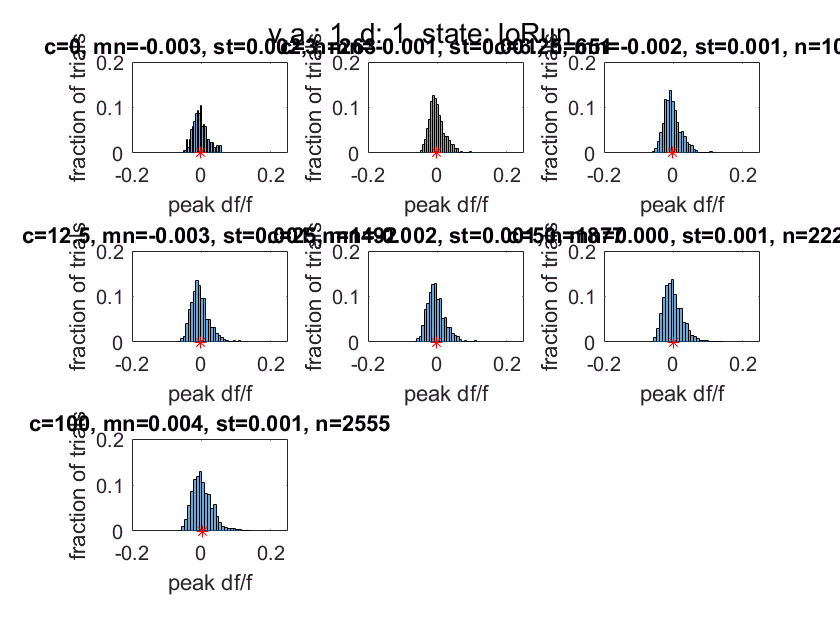

sumNumTrialsEachCon_allSess = 263

sumNumTrialsEachCon_allSess = 651

sumNumTrialsEachCon_allSess = 1078

sumNumTrialsEachCon_allSess = 1492

sumNumTrialsEachCon_allSess = 1877

sumNumTrialsEachCon_allSess = 2220

sumNumTrialsEachCon_allSess = 2555

% GROUP, each sess same color

figure

formatSpec = 'v.a.: %1.f, d: %1.f, state: %s';
titleText = sprintf(formatSpec,visArea,durat,state);
suptitle(titleText)

clear d
for d = durat
    
    clear i
    for i = visArea
        
        clear dthithCthNth_pkDfEachTrial
        dthithCthNth_pkDfEachTrial = []; 
        
        clear sumNumTrialsEachCon_allSess
        
        clear c
        for c = cont
                
            clear n
            for n = sess
  
                dthithCthNth_pkDfEachTrial = [dthithCthNth_pkDfEachTrial,allSess_allConsAllPtsAllDurs_pkDfEachTrial{1,n}{1,d}{1,i}{1,c}];
                
                % for nth trial, cth contrast, save num of trials at this contrast
                numTrialsEachCon_allSess(n,c) = length(dthithCthNth_pkDfEachTrial);
                
            end % end n loop - now have all mean peak df values for each trial, all sessions pooled
            % but for only 1 con
            
            sumNumTrialsEachCon_allSess = sum(numTrialsEachCon_allSess(:,c))
            % PLOT one con at a time, all sess at once, each subplot
            
            subplot(ceil(sqrt(length(uniqueContrasts))),ceil(sqrt(length(uniqueContrasts))),c) % make a subplot for each contrast
            %title(sprintf('c = %0.3d',uniqueContrasts(c)))
                
            h1 = histogram(dthithCthNth_pkDfEachTrial,numBins,'Normalization','probability');
            
            clear mnDf
            mnDf = mean(dthithCthNth_pkDfEachTrial);
            clear y
            y = 0;
        
            hold on
                
            stdev = (std(dthithCthNth_pkDfEachTrial))/(sqrt(length(dthithCthNth_pkDfEachTrial)));
            
            h2 = scatter(mnDf,y,'*','r');
            
            formatSpec = 'c=%s, mn=%0.3f, st=%0.3f, n=%1.0f';
            title(sprintf(formatSpec,cons4axes{c},mnDf,stdev,sumNumTrialsEachCon_allSess));
            %title(uniqueContrasts(c))
            
            xlabel('peak df/f')
            ylabel('fraction of trials')
            ylim(yLimit)
            xlim(xLimit)
            
            %set(gca,'XTick',-0.1:0.05:0.2)
            %set(gca,'XTickLabel',-0.1:0.1:0.2)
            
            %hold on  
            
        end % end c loop
        
    end % end i loop

end % end d loop

% OLD HISTO CODE, deconstructed (original on metascript1)

clear allSess_dthIthAllCons_pkDfEachTrial % b/4 each new group analysis,
% clear struct that holds pk df values for each trial at each con 

clear n
for n = 1:length(nGroup)

    % clear nth all cons struct before each new dur/session
    clear allConsAllPtsAllDurs_pkDfEachTrial
        
    clear d  % for each duration
    for d = durat % duration variable 
        
        clear dthAllConsAllPts_pkDfEachTrial
        
        % for one POINT
        clear i  
        for i = visArea
    
            clear c % for each contrast
            for c = cont
                
                % this is for storing different length-ed cth trial vectors for one contrast, all sessions..
                % new one for each contrast, gets collected in struct array after
                %clear dthIthCthCon_pkDfEachTrial
                %dthIthCthCon_pkDfEachTriall = []; 
             
                % get CTH DTH STAT trials
                
                clear dthCthTrials
                dthCthTrials = conAndDurOrderedByTrialMeetCriteria(1,:) == uniqueContrasts(c) & conAndDurOrderedByTrialMeetCriteria(2,:) == uniqueDurations(d);
                
                clear idxCthDthTrial
                idxCthDthTrial = find(dthCthTrials == 1);
                 
                clear nthIdxCthDthSTATtrials
                idxCthDthSTATtrials = intersect(idxCthDthTrial,idxStatTrials);
                    
                clear numIdxCthDthSTATtrials
                numIdxCthDthSTATtrials = length(idxCthDthSTATtrials)
                
                % GET DFof for PEAK FRAMES
                
                % take df/f data for ith pt, peak frames, cth dth stat trials
                allPeakFramesCthDthTrialsIthPt = squeeze(PTSdfof(i,peakFrameIdx,idxCthDthSTATtrials)); 
                meanPeakFramesCthDthTrialsIthPt = mean(allPeakFramesCthDthTrialsIthPt,1); % gives 1 x #trials
                % ^ CANT do: store output vectors for each contrast
                % b/c every vectoris a different length (num trials), so can't 'collect'
                % Better to just plot directly on the subplot here
                    
                % get BASELINE @ cth dth state trials
                
                clear allBaselineFrames
                allBaselineFrames = squeeze(PTSdfof(i,baselineIdx,idxCthDthSTATtrials));
                % get one mean baseline value over all frames & trials
                meanBaselineFrames = mean(allBaselineFrames,1); % mean over frames
                meanBaselineFrames = mean(meanBaselineFrames,2); % mean over trials
                
                % SUBTract BASeline from vector of mean df/f across peak frames, cthdth stat trials
        
                meanPeakFramesCthDthTrialsIthPtMinusBase = meanPeakFramesCthDthTrialsIthPt-meanBaselineFrames;
                % ^this is a 1 x # trials vector
                
                clear dthIthCthCon_pkDfEachTrial
                dthIthCthCon_pkDfEachTrial = meanPeakFramesCthDthTrialsIthPtMinusBase;
                % SAVE EACH CTH mean Df for peak frames of cth dth stat trials
                % this is all trials at this stim cond, nth session
                %dthIthCthCon_pkDfEachTrial = [allSessCthPeakDfEachTrial,meanPeakFramesCthDthTrialsIthPtMinusBase]; 
                %meanAllSessCthPeakDfAcrossTrials = mean(allSess_dthIthCthCon_pkDfEachTrial);
                
                % STDEV
                % so stderr should take the mean over *sessions* 
                % for 1 session only:
                %stdev = std(allSessCthPeakDfEachTrial)/sqrt(length(allSessCthPeakDfEachTrial));
                
                % collect trial vectors (diff num trials each contrast & session) in struct array
                dthIthAllCons_pkDfEachTrial{1,c} = dthIthCthCon_pkDfEachTrial;
               
            end % end c loop - move to next contrast/subplot
            
            % collect for all pts
            dthAllConsAllPts_pkDfEachTrial{1,i} = dthIthAllCons_pkDfEachTrial;
                    
        end % end i loop (only 1 point
        
        % colelct for all durs
        allConsAllPtsAllDurs_pkDfEachTrial{1,d} = dthAllConsAllPts_pkDfEachTrial;
        
    end % end d loop (only 1 dur)

% for each session, store the struct w/ pk df for each trial at every con inside another struct
allSess_allConsAllPtsAllDurs_pkDfEachTrial{1,n} = allConsAllPtsAllDurs_pkDfEachTrial;
                    
end % end n loop

% tip - index like this -
% allSess_allConsAllPtsAllDurs_pkDfEachTrial{1,n}{1,d}{1,i}{1,c}

figure
formatSpec = 'vis area: %1.f (STAT & RUN)';
titleText = sprintf(formatSpec,visArea);
%suptitle(titleText)

numBins = 25;

yMax = 0.2;
yLimit = [0 yMax];

xMax = 0.3;
xMin = -0.2;
xLimit = [xMin xMax];
xTickRange = [-0.1:0.05:xMax];
xTickLabelRange = [-0.1:0.1:xMax];

% end % end n loop - 
%have vector for all trials across all sessions at 1 contrast now
% move to next contrast
    
%allSessMeanPeakFramesCthDthTrialsIthPtMinusBase = 
% PLOT - one contrast at a time

% once I have the peak activity for the cth contrast for all trials across all sessions, 
% I can make a histogram

subplot(ceil(sqrt(length(uniqueContrasts))),ceil(sqrt(length(uniqueContrasts))),c) % make a subplot for each contrast
%title(sprintf('c = %0.3d',uniqueContrasts(c)))
    
h1 = histogram(allSessCthPeakDfEachTrial,numBins,'Normalization','probability');
%histogram(allSessCthPeakDfEachTrial,numBins)
%hist(allSessCthPeakDfEachTrial,numBins)
hold on
%             
clear x_axis
x_axis = meanAllSessCthPeakDfAcrossTrials;
clear y_axis
y_axis = 0;

h2 = scatter(x_axis,y_axis,'*','r');

formatSpec = 'c=%s, mn=%0.3f, st=%0.3f';
title(sprintf(formatSpec,cons4axes{c},meanAllSessCthPeakDfAcrossTrials,stdev));

%title(uniqueContrasts(c))

xlabel('peak df/f')
ylabel('fraction of trials')
ylim(yLimit)
xlim(xLimit)

%set(gca,'XTick',-0.1:0.05:0.2)
%set(gca,'XTickLabel',-0.1:0.1:0.2)

hold on  

%stDevEachSessPerCon(:,:,c) = stDevEachSess;